vid=VideoReader("PulsVid.mp4");
fil = load("PulsData.txt");

R=transpose(fil(:,1));
G=transpose(fil(:,2));
B=transpose(fil(:,3));
R=R-mean(R);
G=G-mean(G);
B=B-mean(B);

fps=vid.FrameRate;
N=length(R);
t=0:1/fps:(N-1)/fps;

R=highpass(R,50/60,fps); %Fjerner komponenter/frekvenser under 40 BPM
R=lowpass(R,230/60,fps) %Fjerner komponenter/frekvenser over 230 BPM

R =    -0.0120   -0.0157   -0.0133   -0.0085   -0.0049   -0.0019    0.0021    0.0066    0.0100    0.0121    0.0136    0.0143    0.0135    0.0111    0.0078    0.0045    0.0011   -0.0035   -0.0087   -0.0118   -0.0108   -0.0084   -0.0090   -0.0144   -0.0207   -0.0211   -0.0108    0.0077    0.0229    0.0206    0.0001   -0.0172   -0.0059    0.0297    0.0527    0.0388    0.0099    0.0020    0.0113    0.0075   -0.0084   -0.0104   -0.0134   -0.0624   -0.1335   -0.1320   -0.0339    0.0566    0.0602    0.0374



h=transpose(hann(N));
N_fft=2^(14);
df=fps/N_fft

df = 9.9329e-04

f=(-fps/2:df:fps/2-df)*60; % Frekvens i BPM
R_fft=abs(fftshift(fft(h.*R,N_fft))); % Amplituderespons
S_r=20*log10(R_fft/max(R_fft));
[r_RR,lag] = xcorr(R,R);
lag=lag/fps*60;

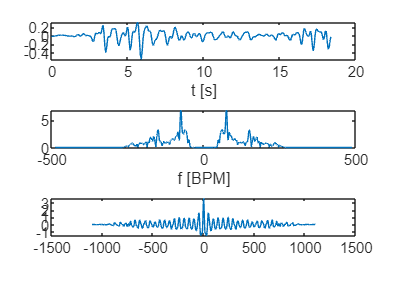

figure;

subplot(3,1,1);
plot(t,R);
xlabel("t [s]");

subplot(3,1,2);
plot(f,R_fft);
xlabel("f [BPM]");

subplot(3,1,3);
plot(lag,r_RR);

[~, puls_index] = sort(R_fft, 'descend'); % De 2 første verdiene vil gi x-verdi til de 2 største toppene

excluded = [puls_index(1), puls_index(2)]

excluded =         6937        9449


included = ~ismember(1:N_fft, excluded);
SNR_f=(R_fft(puls_index(2)))/mean(R_fft(included));

disp("Puls: "+f(puls_index(2))+" BPM");

Puls: 74.8541 BPM


disp("SNR_f: "+SNR_f+" dB");

SNR_f: 11.5648 dB
